## The Fiedler Number and Fiedler Vector 

Construct and plot an adjacency example matrix $\mathbf{A}$. Edges between nodes numbered 1 - 19 are specified in pairs in vector `ij`. The matrix is constructed by converting the upper triangular matrix for a dense (full) adjacency matrix by adding it's transpose/ 

ij = [9 12; 9 13; 12 13; 12 14; 13 14; 14 19; 
      13 19; 13 18; 19 18; 18 15; 18 16; 16 17; 
      15 17; 17 6; 17 5; 6 4; 5 4; 4 11; 11 3; 
      11 10; 3 2; 10 2; 10 8; 8 1; 1 7; 8 7];

% build full matrix from sparse edges 
A = full(sparse(ij(:,1),ij(:,2),1, 19, 19)); 
A = A + A'

A =      0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     1     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1    

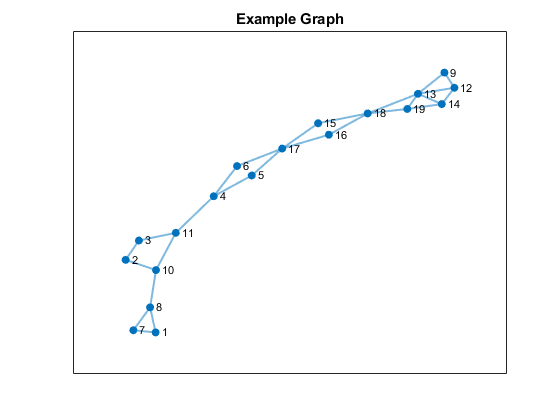


% plot the graph
p = plot(graph(A));
p.MarkerSize = 5;
p.LineWidth = 1.5;
title('Example Graph');

Plot the matrix $\mathbf{A}$.

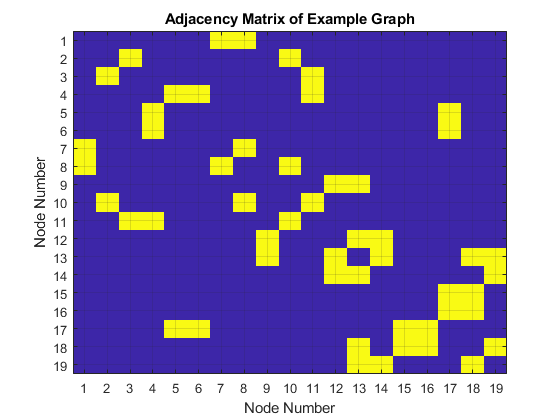

imagesc(A); %useful function for visualizing large matrices
xlabel('Node Number');
ylabel('Node Number');
set(gca,'Xtick',0:length(A));
set(gca,'Ytick',0:length(A));
grid on;
title('Adjacency Matrix of Example Graph');

Construct the Laplacian via the equation below

    
$$\mathbf{L = D - A}$$


Plot it:

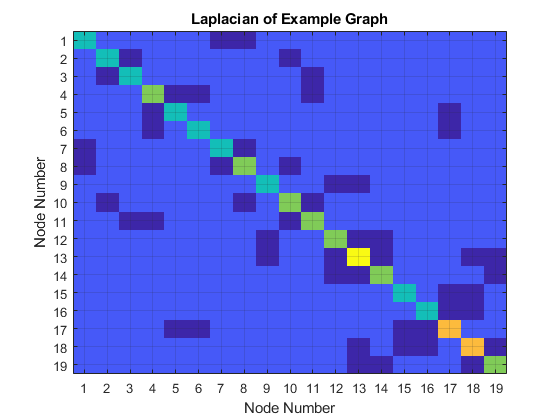

% calculate degree matrix and construct the Laplacian
D = diag(sum(A));
L = D - A;

% visualize the L matrix
imagesc(L);
xlabel('Node Number');
ylabel('Node Number');
set(gca,'Xtick',0:length(L));
set(gca,'Ytick',0:length(L));
grid on;
title('Laplacian of Example Graph');

Compute the eigvalues (`S)` and eigenvectors (`V)` of $\mathbf{L}$. Plot the 19 eigenvalues in ascending order in a plot called a scree plot.

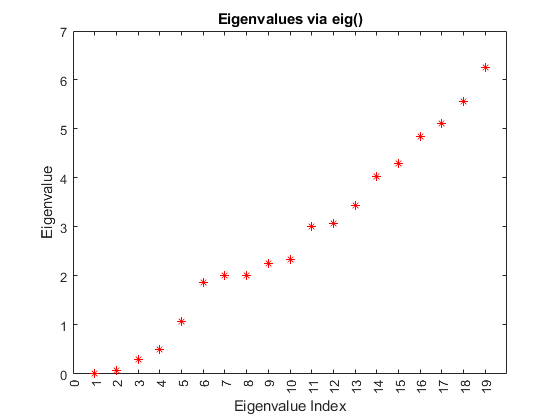

% compute the eigenvalues and eigenvectors of the Laplacian
[V, S] = eig(L);
eigenvalues = diag(S); % convert square diagonal matrix to 1D vector

% plot a scree plot
plot(eigenvalues, 'r*');
xlabel('Eigenvalue Index');
ylabel('Eigenvalue');
set(gca,'Xtick',0:length(eigenvalues));
xtickangle(90);
title('Eigenvalues via eig()');

Note that when constructing the eigenvalues and eigenvectors using `svd()` that the default ordering of the eigenvalues and eigenvectors is reversed:

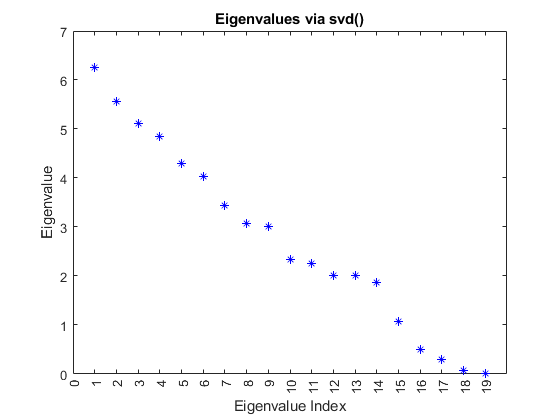

% compute eigenvector and values using the svd() function
[u, s, vh] = svd(L);
svd_eigvalues = diag(s);

% plot the eigenvalues in a scree plot
plot(svd_eigvalues, 'b*');
xlabel('Eigenvalue Index');
ylabel('Eigenvalue');
set(gca,'Xtick',0:length(svd_eigvalues));
xtickangle(90);
title('Eigenvalues via svd()');

This is important because we want the second smallest eigenvalue and eigenvector, so we must pay attention to ordering. I will use `svd()` here. We can extract the **Fiedler number **from the vector of eigenvalues, `S:`

feidler_index = length(svd_eigvalues) - 1;
feidler_value = svd_eigvalues(feidler_index)

feidler_value = 0.0692

I plot the values of the **Feidler vector **for each node in the graph. We obtain the singular value decomposition of the matrix $\mathbf{L}$ :

    
$$\mathbf{L} =\mathbf{ U \Sigma V^T}$$


Using MATLAB we get the variables `[u, s, vh] = svd(L)` corresponding to the matrices $\mathbf{U}$, $\mathbf{\Sigma}$, and $\mathbf{V^T}$. The Fiedler vector is the **column of **$\mathbf{U}$ corresponding the the second smallest eigenvalue of $\mathbf{L}$. This means the second-to-last column if you compute the eigenvectors using the function `svd()`. The variable `feidler_index` is the length of the diagonal of $\mathbf{\Sigma}
$ minus 1, which is the indexed position of the second to last element. We can use this index to get the second-to-last column from $\mathbf{U}$ and plot it:

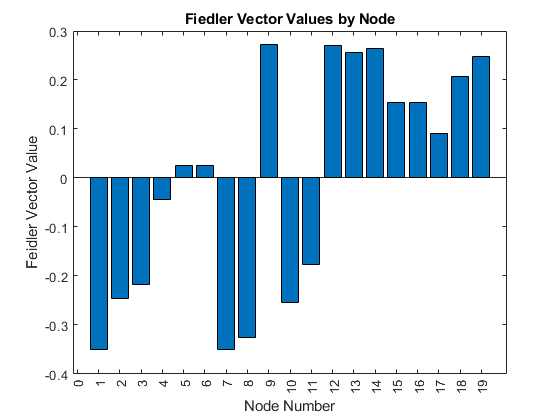

feidler_vector = u(:,feidler_index);
bar(feidler_vector);
xlabel('Node Number');
ylabel('Feidler Vector Value');
set(gca,'Xtick',0:length(u));
xtickangle(90);
title('Fiedler Vector Values by Node');

Notice that we can use the sign from the Fiedler vector to partition the graph. First we create a boolean array with 19 elements that has a 1 where the Fielder vector value is greater than 0. The array, called `signs`, has zeros in the positions where the `fiedler_vector` is negative.

signs = feidler_vector > 0

signs = 19×1 logical array
   0
   0
   0
   0
   1
   1
   0
   0
   1
   0


This logical array may be used to "reset" the colors of specific nodes in the original graph plot. This means we are plotting the original graph, but changing the color of the nodes based on their value in the Fiedler vector. In this case, the Fiedler vector is the second-to-last column of $\mathbf{U}$, which has 19 entries (one for each node).

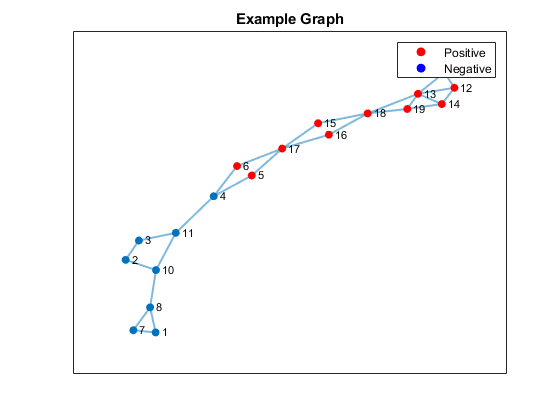

p = plot(graph(A));
hold on;

% change the color of every node where the variable `signs == 1`
highlight(p, signs, 'NodeColor', 'r');
p.MarkerSize = 5;
p.LineWidth = 1.5;
title('Example Graph');

% create a "dummy" legend
p(1) = plot(NaN,NaN,'or', 'MarkerFaceColor', 'r');
p(2) = plot(NaN,NaN,'ob', 'MarkerFaceColor', 'b');
legend(p, 'Positive','Negative');
hold off;

Next we can look at the next eigenvectors, i.e., those corresponding to the next $k$ largest eigenvalues starting from the Fiedler number. On the scree plot, we *start* with the eigenvector corresponding to the second-smallest eigenvalue and add columns of $\mathbf{U}$ corresponding to increasingly large eigenvvalues. 

To do this, I use the index of the second smallest eigenvalue and the indices preceeding it to extract the eigenvectors from the columns of the matrix $\mathbf{U}$. This would need to be re-written if you are using `eig()` to compute the eigenvectors. The function `flip()` is used on the second dimension in order to place the Fiedler vector as the first column rather than the last column, followed by eigenvectors that correspond to increasingly large eigenvalues of the Laplacian.

Each row in this matrix corresponds to a node in the network. **Take note of the positive and negative signs of the elements.**

k = 3; % arbitrarily chosen - but second to last plot is hardcoded to k=3!

% extract the k columns to the LEFT of the fiedler vector
u_k_reverse_order = u(:, feidler_index - (k-1) : feidler_index);
u_k = flip(u_k_reverse_order, 2)

u_k =    -0.3502   -0.3427    0.2823
   -0.2450    0.1199   -0.4371
   -0.2182    0.1809   -0.4454
   -0.0433    0.3093    0.0770
    0.0246    0.3245    0.2121
    0.0246    0.3245    0.2121
   -0.3502   -0.3427    0.2823
   -0.3259   -0.2439    0.1415
    0.2723   -0.2465   -0.1722
   -0.2549    0.0243   -0.2107


It's illuminating to investigate the signs of these eigenvectors. If the value in the eigenvector is greater than zero, we set the the value to 1. Otherwise the value is set to zero. Yellow indicates that the eigenvector value for a particular node is greater than zero and purple indicates that the eigenvector value is negative.

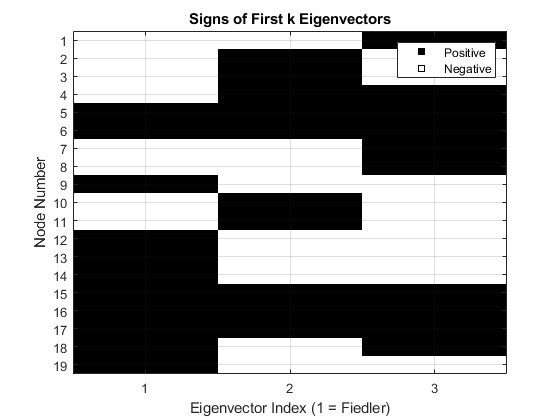

% 'digitize' the array from the cell above
u_k_digit = u_k;
u_k_digit(:, 1) = u_k_digit(:, 1)  > 0;
u_k_digit(:, 2) = u_k_digit(:, 2)  > 0;
u_k_digit(:, 3) = u_k_digit(:, 3)  > 0;

% plotting as above
close all;
imagesc(u_k_digit);

% set the colormap
cmap = [1 1 1; 0 0 0];
colormap(cmap);

% plot params
hold on;
xlabel('Eigenvector Index (1 = Fiedler)');
ylabel('Node Number');
grid on;
set(gca,'Xtick',0:length(u_k_digit));
set(gca,'Ytick',0:length(u_k_digit'));

title('Signs of First k Eigenvectors');

% create a "dummy" legend
p(1) = plot(NaN,NaN,'sk', 'MarkerFaceColor', 'k');
p(2) = plot(NaN,NaN,'sk', 'MarkerFaceColor', 'w');
legend(p, 'Positive','Negative');
hold off;

Lastly, we consider how the graph may be partitioned by the signs of these eigenvectors. The original graph is colored by the "digitized" $k$ eigenvectors. This plot will currently only work for $k =3$ because use the boolean representation of the matrix above as "color codes" for each of the nodes. This is also why I manually change a number of nodes (6, 5, 17, 15, 16) to black, since the color code here would have been `[0 0 0]`, which is not very easy to see!

What do you observe?

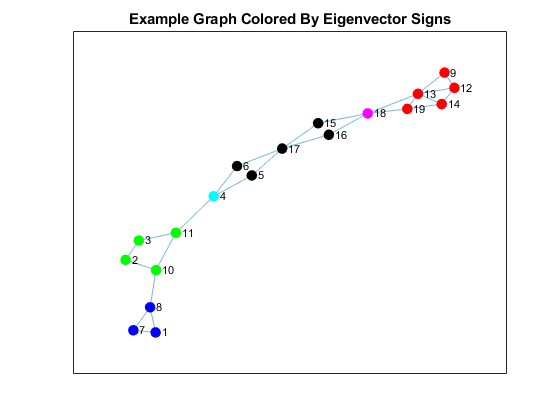

p = plot(graph(A), 'NodeColor', u_k_digit);
p.MarkerSize = 7;

% get the nodes with all zero values manually
col_sums = sum(u_k_digit, 2);
pesky_nodes = col_sums == 3; % set white nodes to different color
highlight(p, pesky_nodes, 'NodeColor', 'black');
title(['Example Graph Colored By Eigenvector Signs']);

.